## 1) Esercizio di riepilogo analisi univariate variabili quantitative

% Caricare in memoria la table di dimensione 103x7 contenente 6 indicatori
% di 107 province italiane tramite l'istruzione
% load citiesItaly.mat
% Calcolare e commentare gli indici di asimmetria e di curtosi
% della variabile unemploy (tasso di disoccupazione) utilizzando la
% funzione grpstats. Mostrare l'output in una table come segue

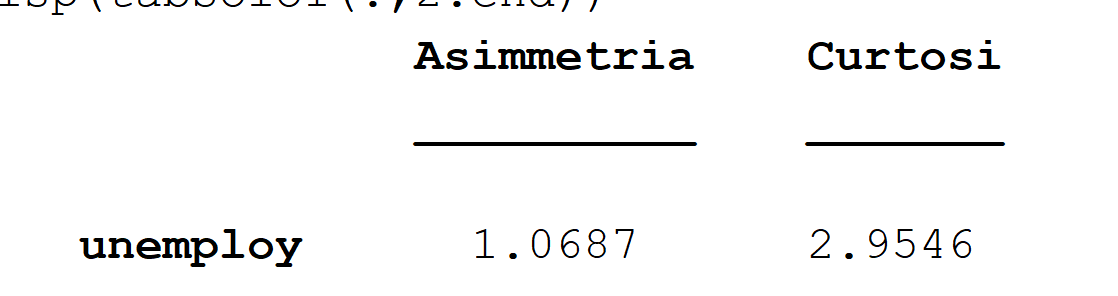

% Creare la table (denominata statTable) di dimensione 7x5 contenente, medie, mediane,
% deviazioni standard, indici di asimmetria e curtosi per ogni variabile
% del dataset. L'anteprima output di questa table è di seguito

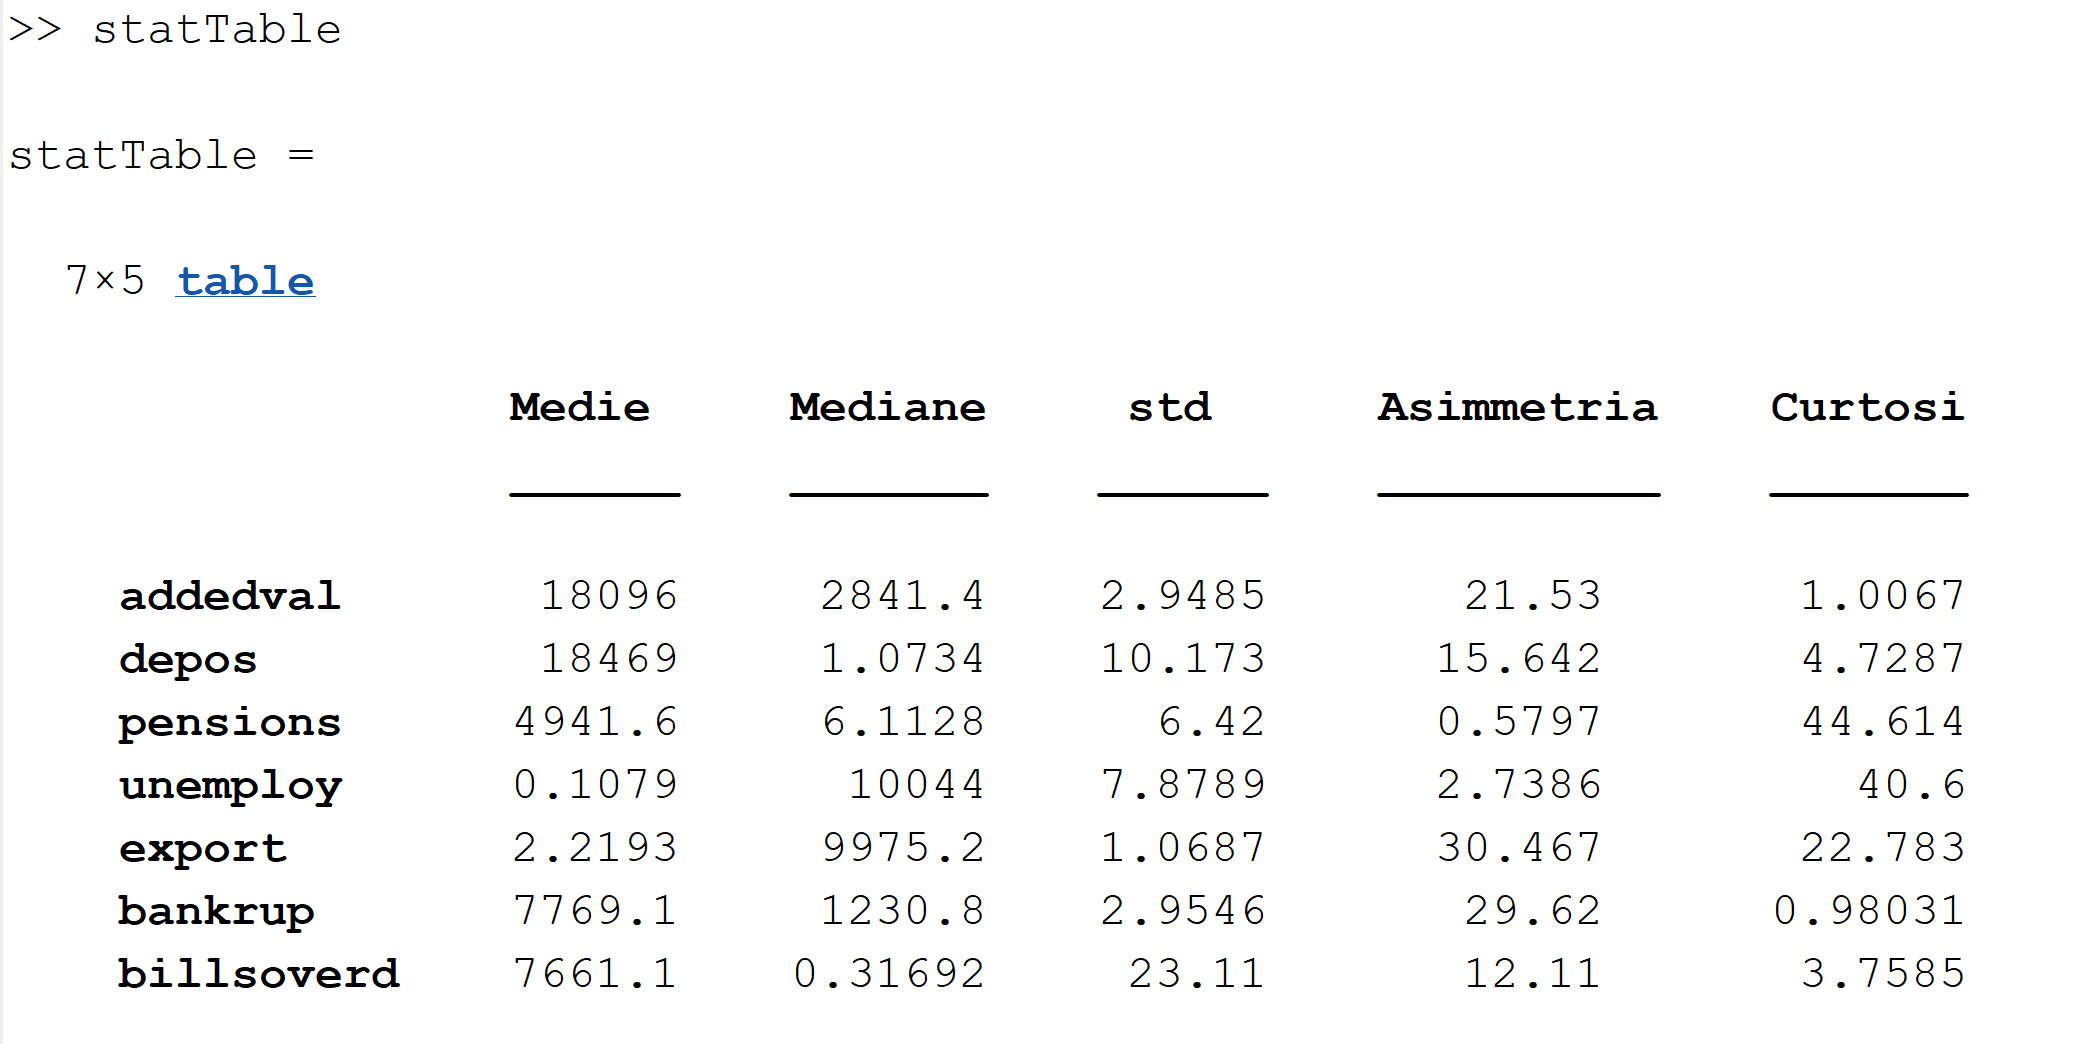

% Creare per ogni variabile standardizzata una table che
% riporta nella colonna j la distribuzione di frequenze per la variabile j.
% j=1, 2, ..., 7
% Utilizzare per ogni variabile le classi
% <-2, -2----- -1.5, ..., 2.5-----3, >= 3

% Suddividere la finestra grafica in un layout di tipo 2x4. Inserire nella
% prima riga della finestra grafica i grafici ad istogramma utilizzando k
% classi (per default utilizzare k=10). Aggiungere al valore della
% variabile k un "numeric spinner" con valore minimo 6, passo 1, massimo 20
% e valore di default 10.
% Aggiungere il nome della rispettiva variabile ad ogni pannello.
% Inserire l'ultima variabile nei pannelli 7 e 8

% Le prime 46 righe della table citiesItaly si riferiscono alle province
% del nord e le rimanenti alle province del centro e sud Italia.
% Confrontare i quantili 0.01 0.05, 0.10, ..., 0.90, 0.95, 0.99 della
% variabile addedval (indicatore del valore aggiunto prodotto da ogni
% provincia) per le province del nord e quelle del centro sud.
% Rappresentare graficamente i quantili delle due distribuzioni e
% commentare il grafico.

% Rappresentare graficamente l'intervallo di confidenza al livello di
% confidenza del 99.9 per cento separato per zona di appartenenza per la
% variabile tasso di disoccupazione

% Suddividere la finestra grafica in un layout di tipo 2x4. Inserire nel
% pannello j il boxplot per la variabile j (j=1, 2, ...,7) separando le
% province del nord da quelle del centro sud. Aggiungere le etichette delle
% province per le unità che risultano anomale.
% Commentare i risultati
% ottenti. L'anteprima output di quest'ultimo grafico è riportato di seguito.



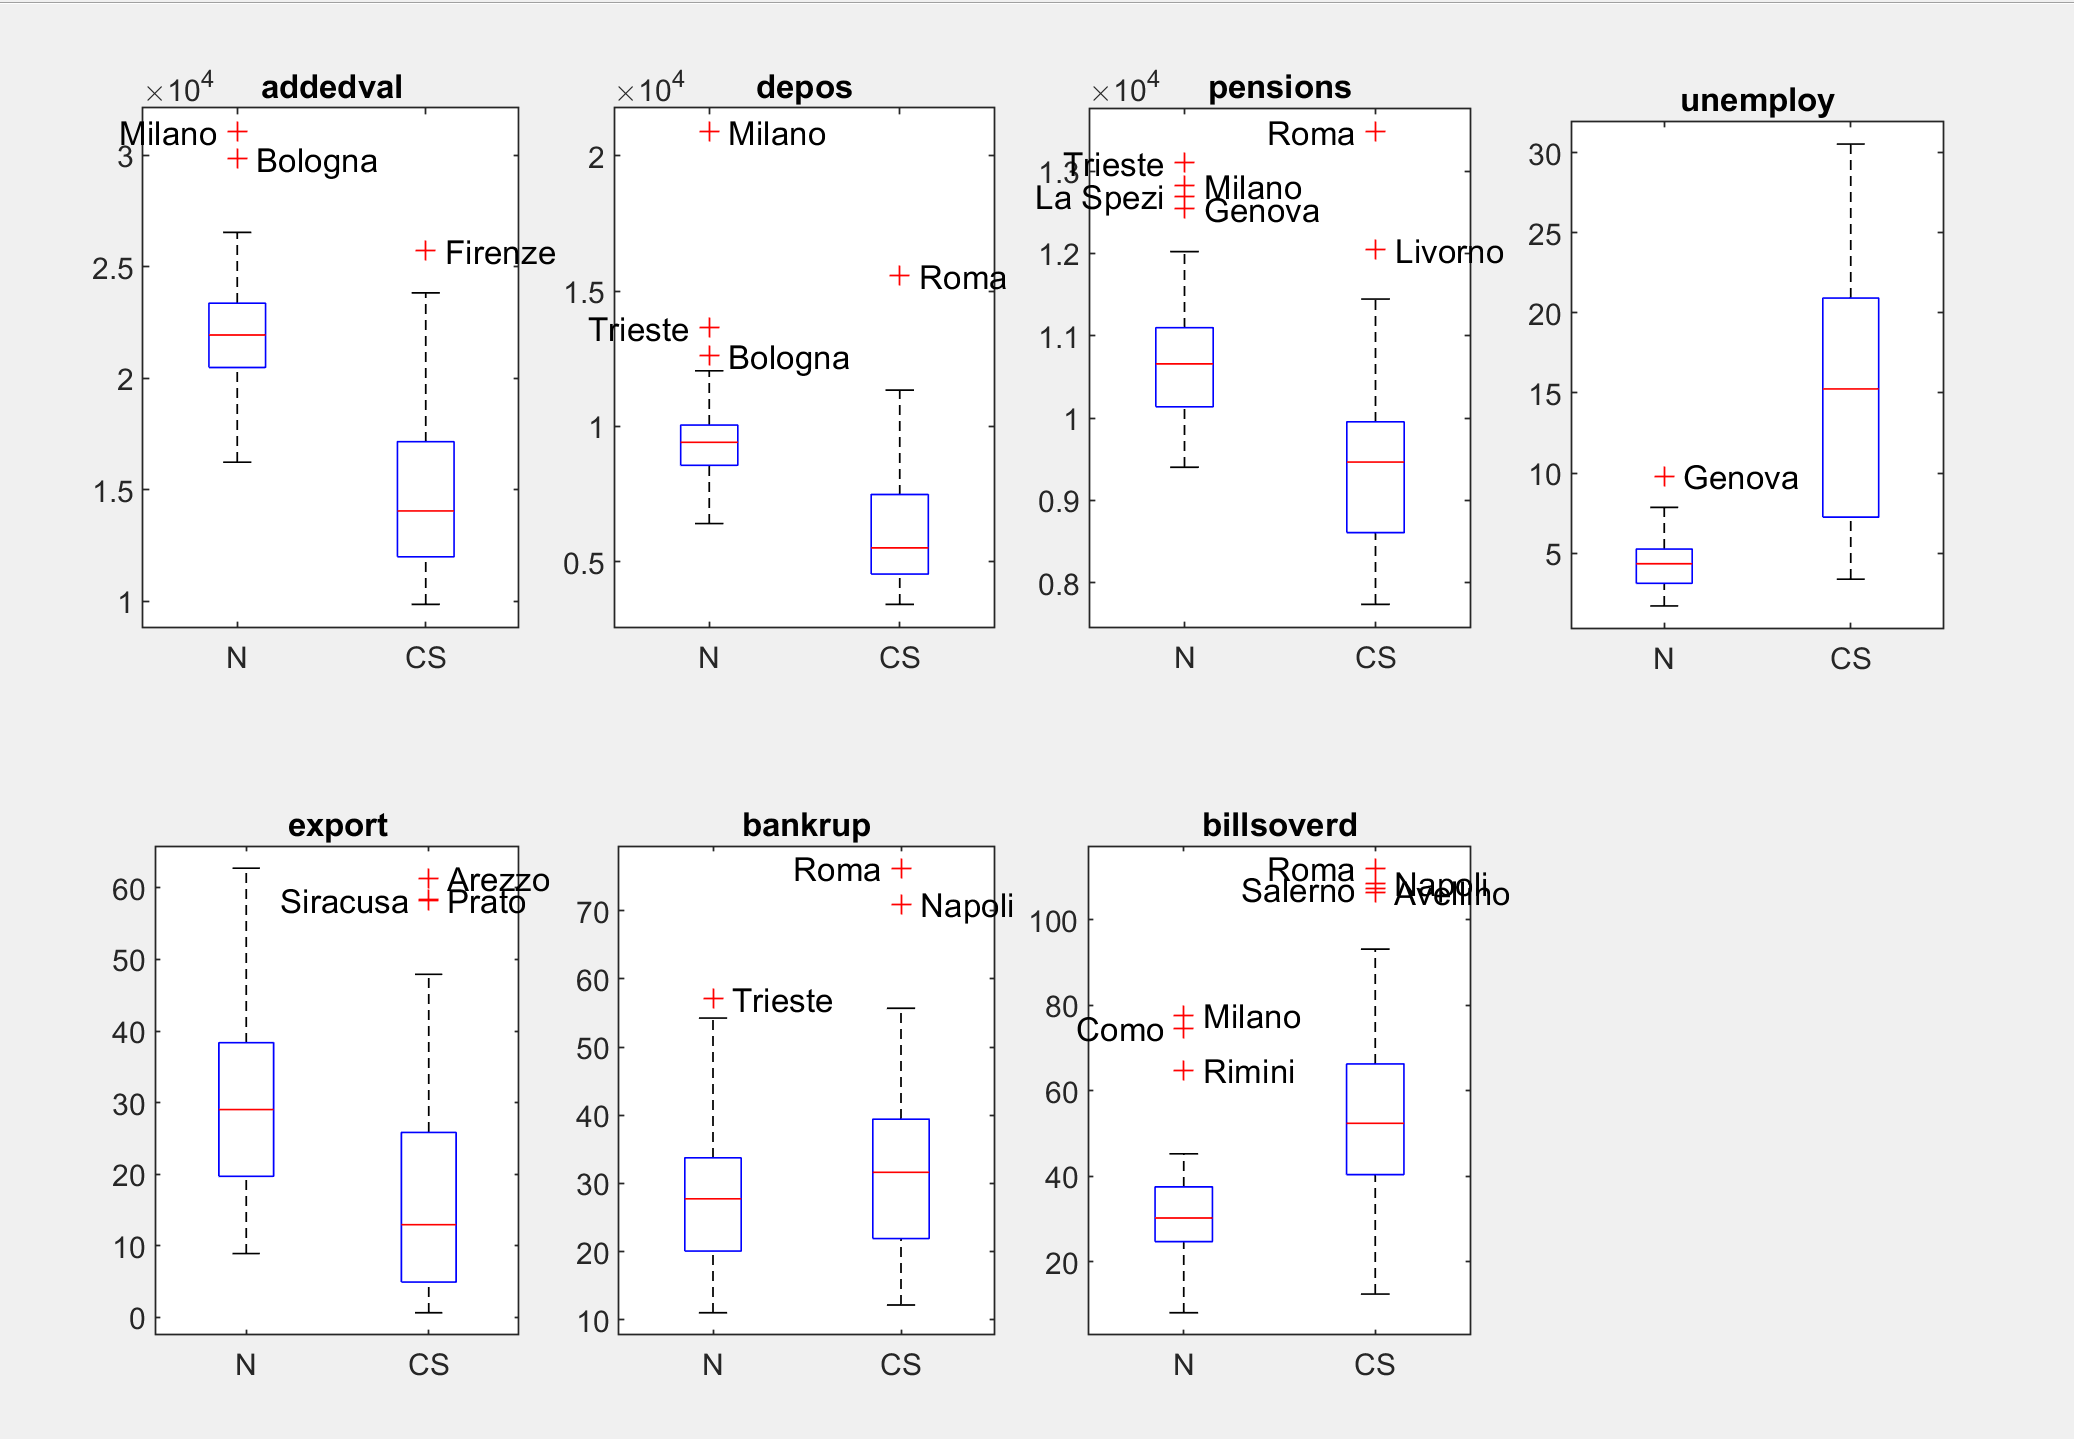

load citiesItaly.mat
vnames=citiesItaly.Properties.VariableNames;
[n,p]=size(citiesItaly);
% Indici di asimmetria solo per variabile unemploy (indice di
% disoccupazione) con nomi personalizzati nelle colonne di output prodotti
% dalla funzione grpstats
statdaCalcolare=["@skewness" "@kurtosis"];
varDautilizzare="unemploy";
tabSolo1=grpstats(citiesItaly,[],statdaCalcolare,'DataVars',varDautilizzare,'VarNames',["n" "Asimmetria" "Curtosi"]);
tabSolo1.Properties.RowNames=varDautilizzare;
disp(tabSolo1(:,2:end))

                Asimmetria    Curtosi
                __________    _______

    unemploy      1.0687      2.9546 




% Medie, Mediane, std, Indici di asimmetria e curtosi per tutte le variabili
IndiciDacalcolare=["@mean" "@median" "@std" "@skewness" "@kurtosis"];
% I primi 5 numeri di tabTutti si riferiscono alle 5 statistiche per la
% prima variabile, ..., gli ultimi 5 numeri di tabTutti si riferiscono alle
% 5 statistiche per l'ultima variabile
tabTutti=grpstats(citiesItaly,[],IndiciDacalcolare);

% I 35 numeri contenuti nelle colonne 2:36 della table tabTutti devono essere
% trasformati (tramite la funzione reshape) in una matrice 7 x 5 come segue
% Prima riga mean, median, std, skewness, kurtosis  per la prima variabile
% Seconda riga mean, median, std, skewness, kurtosis  per la seconda
% variabile
% ...
% Settima riga mean, median, std, skewness, kurtosis  per la settima variabile
% reshape(..., length(IndiciDacalcolare),p) trasforma i 35 numeri 
% in una matrice 5x7 di conseguenza per avere una 7x5 devo fare il
% trasposto
statArray=reshape(tabTutti{1,2:end},length(IndiciDacalcolare),p)';
% Trasformo statArray in una table e aggiungo i nomi delle righe (nomi
% delle variabili originarie) e i nomi delle colonne (nomiStat)
nomiStat=["Medie" "Mediane", "std" "Asimmetria" "Curtosi"];
statTable=array2table(statArray,"RowNames",vnames,"VariableNames",nomiStat);
disp(statTable)

                  Medie     Mediane     std      Asimmetria    Curtosi
                  ______    _______    ______    __________    _______

    addedval       18096     18469     4941.6      0.1079      2.2193 
    depos         7769.1    7661.1     2841.4      1.0734      6.1128 
    pensions       10044    9975.2     1230.8     0.31692      2.9485 
    unemploy      10.173      6.42     7.8789      1.0687      2.9546 
    export         23.11     21.53     15.642      0.5797      2.7386 
    bankrup       30.467     29.62      12.11      1.0067      4.7287 
    billsoverd    44.614      40.6     22.783     0.98031      3.7585 





%%%%%%%%%%%%%%% INIZIO PARTE APPROFONDIMENTI
%% Metodo alternativo per trovare ad esempio gli indici di asimmetria per
% tutte le colonne della table citiesItaly
Indici=varfun(@skewness,citiesItaly);

% Modo alternativo per trovare gli indici per ogni variabile
% In questo caso utilizzo la funzione varfun
func=@(v) [mean(v) median(v) std(v) skewness(v), kurtosis(v)];
% Se avessi voluto utilizzare media e standard deviation per ogni variabile
% func = @(x)[mean(x) std(x)]
esIndici=varfun(func,citiesItaly);
%%%%%%%%%%%%%%% FINE PARTE APPROFONDIMENTI



% Creare per ogni variabile standardizzata una table che
% riporta nella colonna j la distribuzione di frequenze per la variabile j.
% j=1, 2, ..., 7
% Utilizzare per ogni variabile le classi
% <-2, -2----- -1.5, ..., 2.5-----3, >= 3
classi=[-Inf -2:0.5:3 Inf]';
% La matrice DistFreq conterrà in corrispondenza della colonna j, la
% distribuzione di frequenze riferita alla variabile j
% j=1, 2, ..., 7
DistFreq=zeros(length(classi)-1,p);
% Z = Matrice degli scostamenti standardizzati
Z=zscore(citiesItaly{:,:});
for j=1:p
    DistFreq(:,j)=histcounts(Z(:,j),classi);
end
%ClassiNomi = vettore che contiene le etichette delle classi
ClassiNomi="["+string(classi(1:end-1))+ " " +string(classi(2:end))+")";
DistFreqT=array2table(DistFreq,"VariableNames",vnames,"RowNames",ClassiNomi);


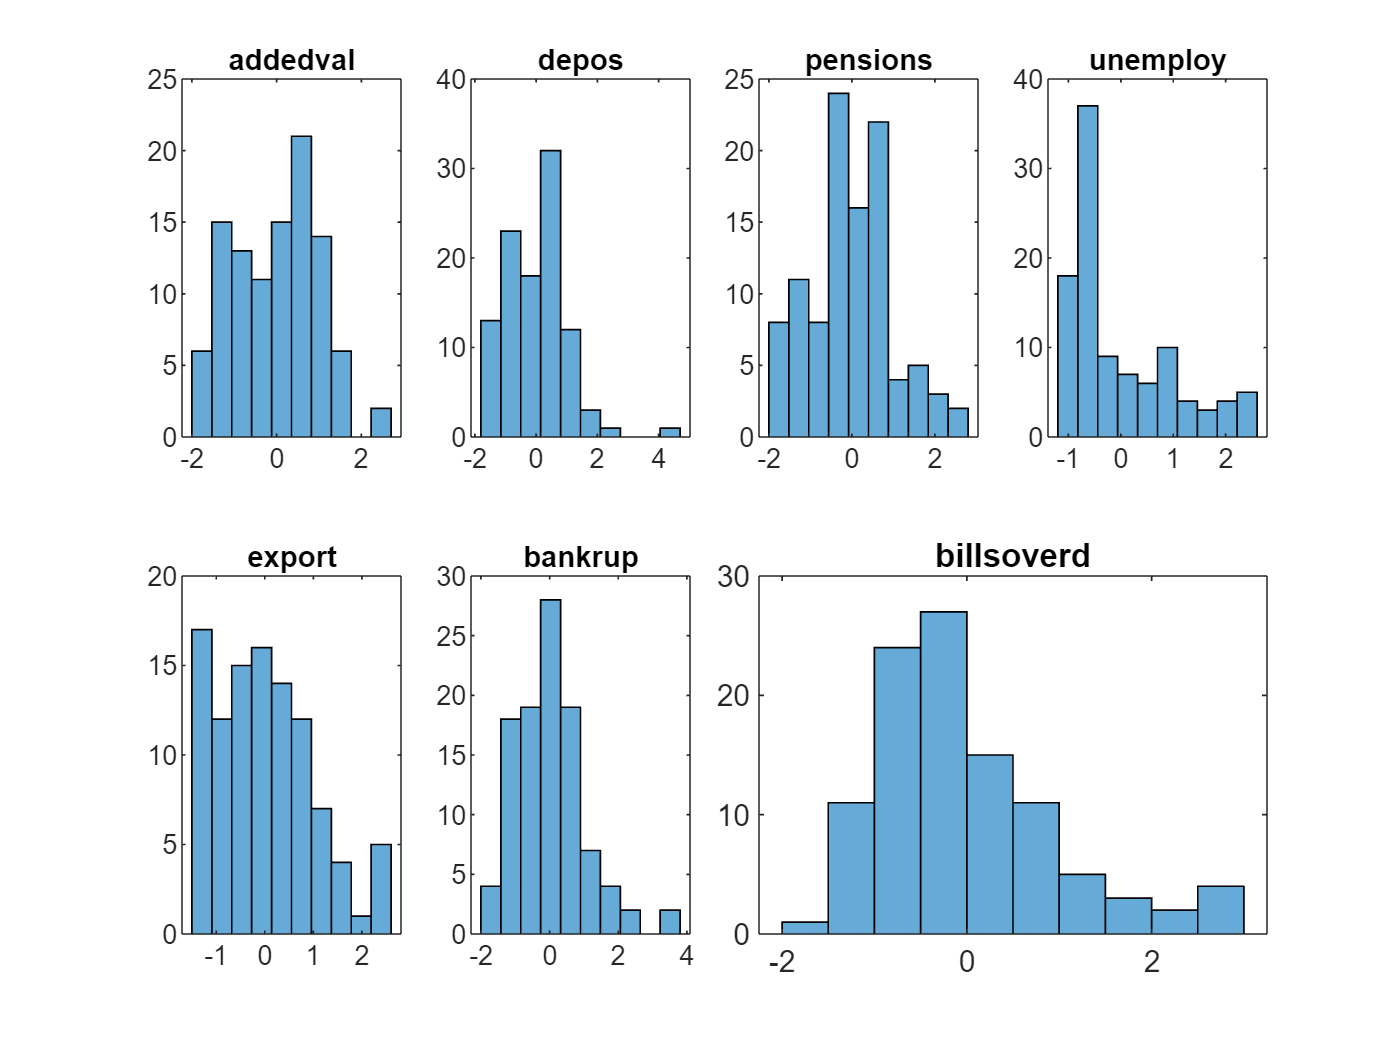


% Suddividere la finestra grafica in un layout di tipo 2x4. Inserire nella
% prima riga della finestra grafica i grafici ad istogramma utilizzando k
% classi (per default utilizzare k=10). Aggiungere al valore della
% variabile k un "numeric spinner" con valore minimo 6, passo 1 massimo 20
% e valore di default 10.

% k= numero di classi
k=10;
for j=1:p
    if j<p
        subplot(2,4,j)
    else
        subplot(2,4,j:j+1)
    end
    histogram(Z(:,j),k)
    title(vnames{j})
end

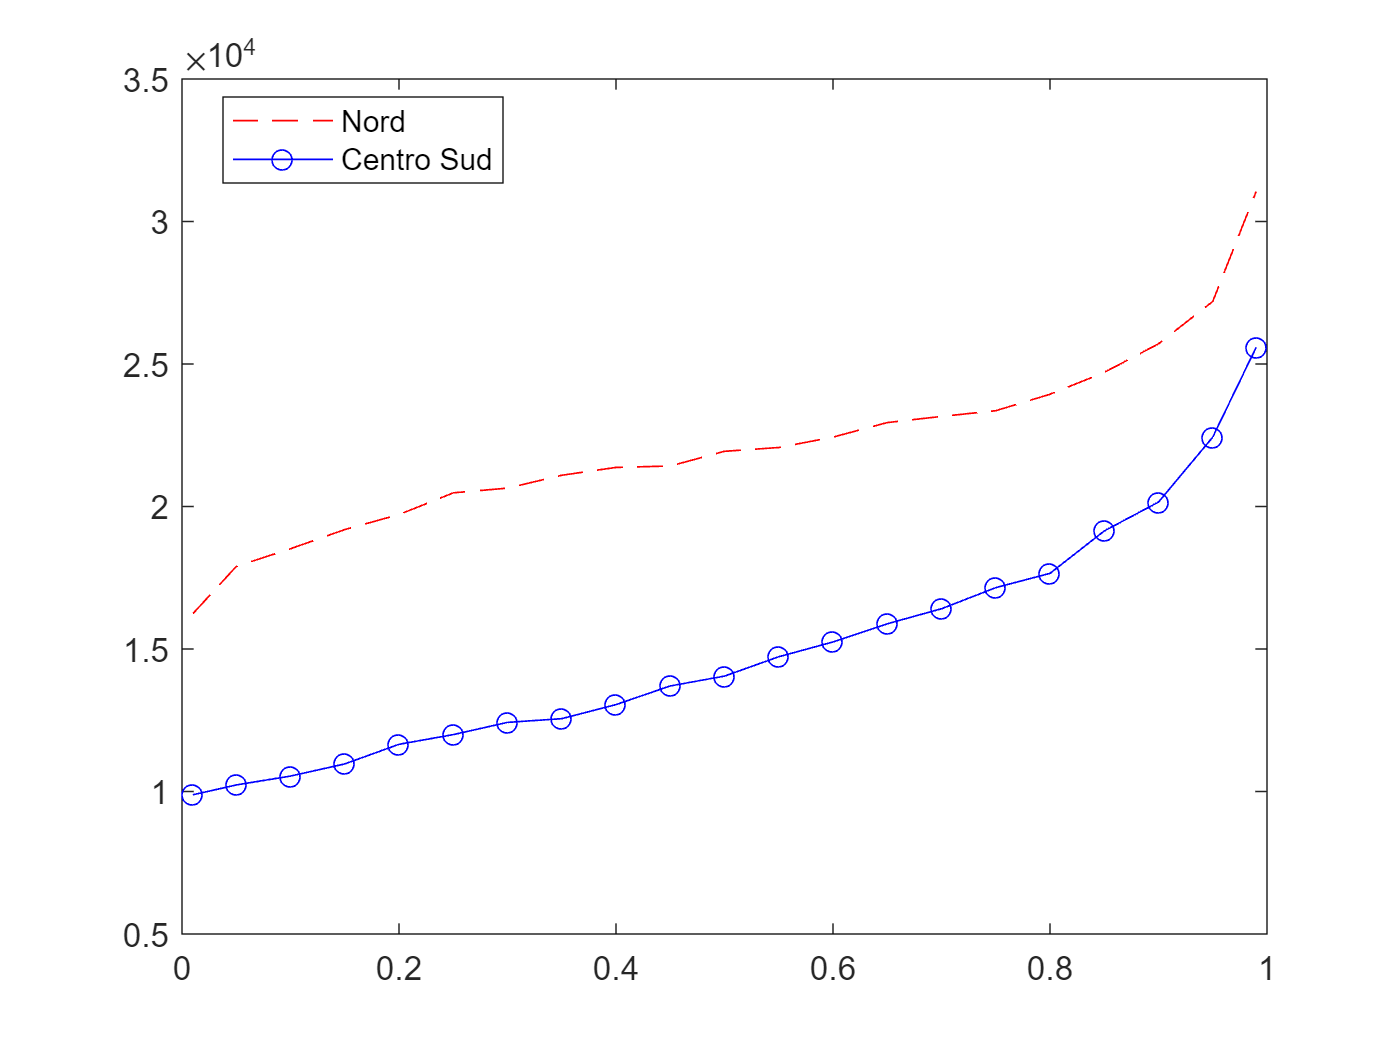

% Analisi con variabile di raggruppamento
% Viene creata la variabile di raggruppamento
% groupvariable = un vettore di stringhe che contiene nelle prime 46
% posizioni la stringa N e per le rimanenti posizioni la stringa CS
groupvariable=[repmat("N",46,1);repmat("CS",n-46,1)];
% boo è una variabile booleana che contiene true in corrispondenza delle
% province del nord.
boo=groupvariable=="N";

% Analisi dei quantili della variabile valore aggiunto separato per le
% province nord e quelle del centro sud

quan=[0.01 0.05:0.05:0.95 0.99];
nomevar="addedval";
qN=quantile(citiesItaly{boo,nomevar},quan);
qCS=quantile(citiesItaly{~boo,nomevar},quan);
figure
plot(quan,qN,'r--',quan,qCS,'b-o')
legend(["Nord" "Centro Sud"],'Location','best')

% Commento i quantili riferiti alle province del nord sono uniformemente
% più elevati di quelli delle province del centro sud.


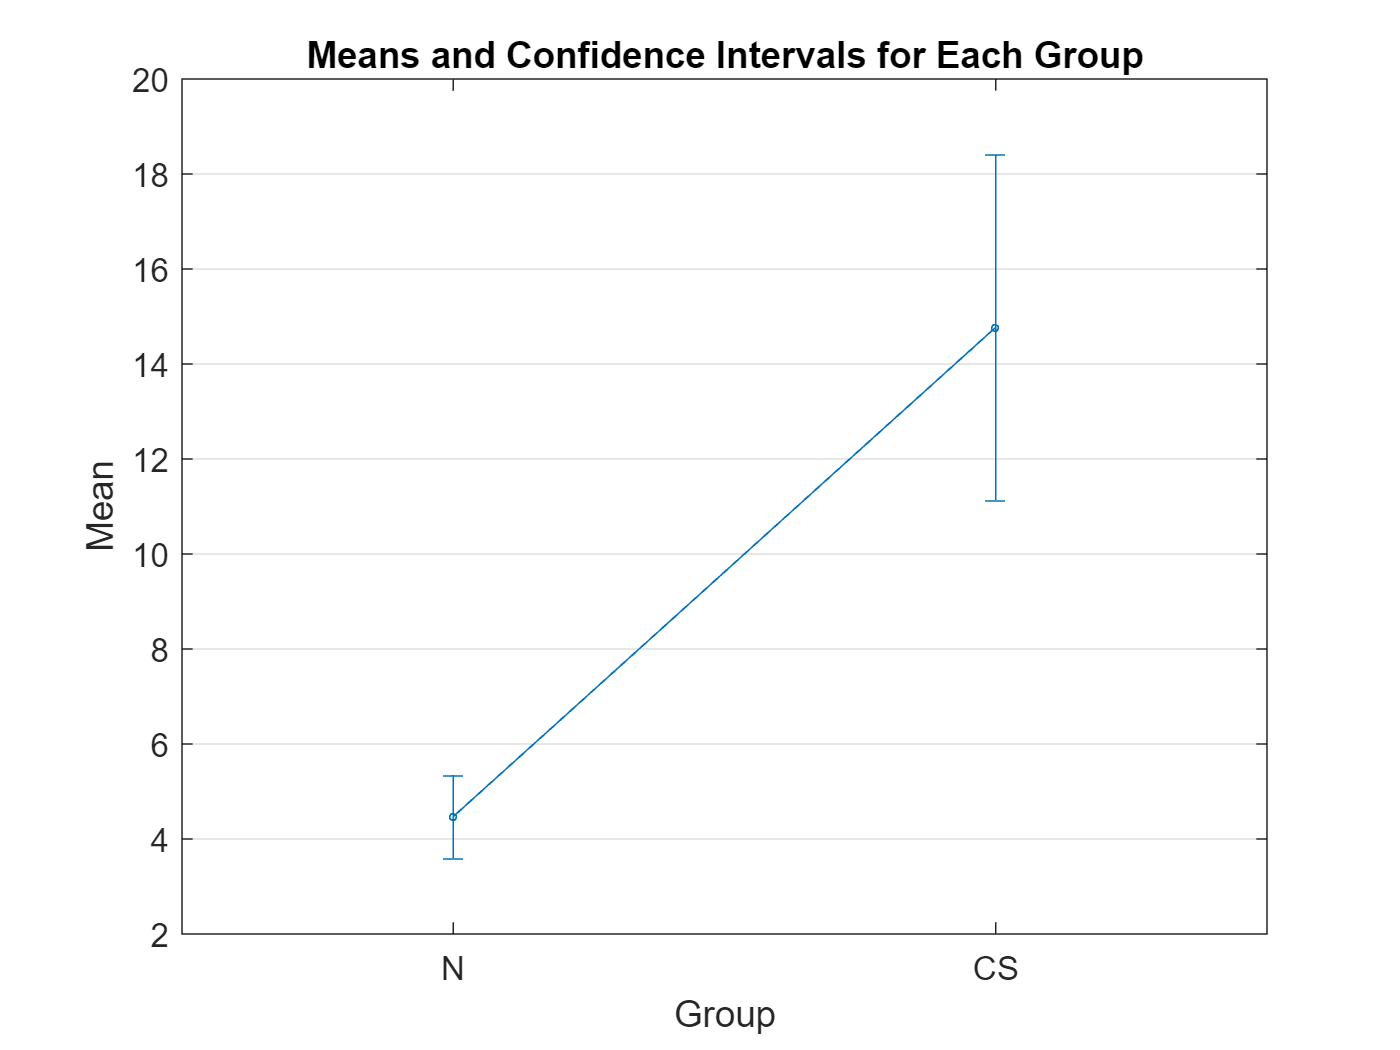

% Rappresentare graficamente l'intervallo di confidenza al livello di confidenza del 99.9 per cento
% separato per zona di appartenenza per la variabile tasso di disoccupazione
grpstats(citiesItaly.unemploy,groupvariable,0.001);

% Commento: i due intervalli di confidenza non si sovrappongono. 

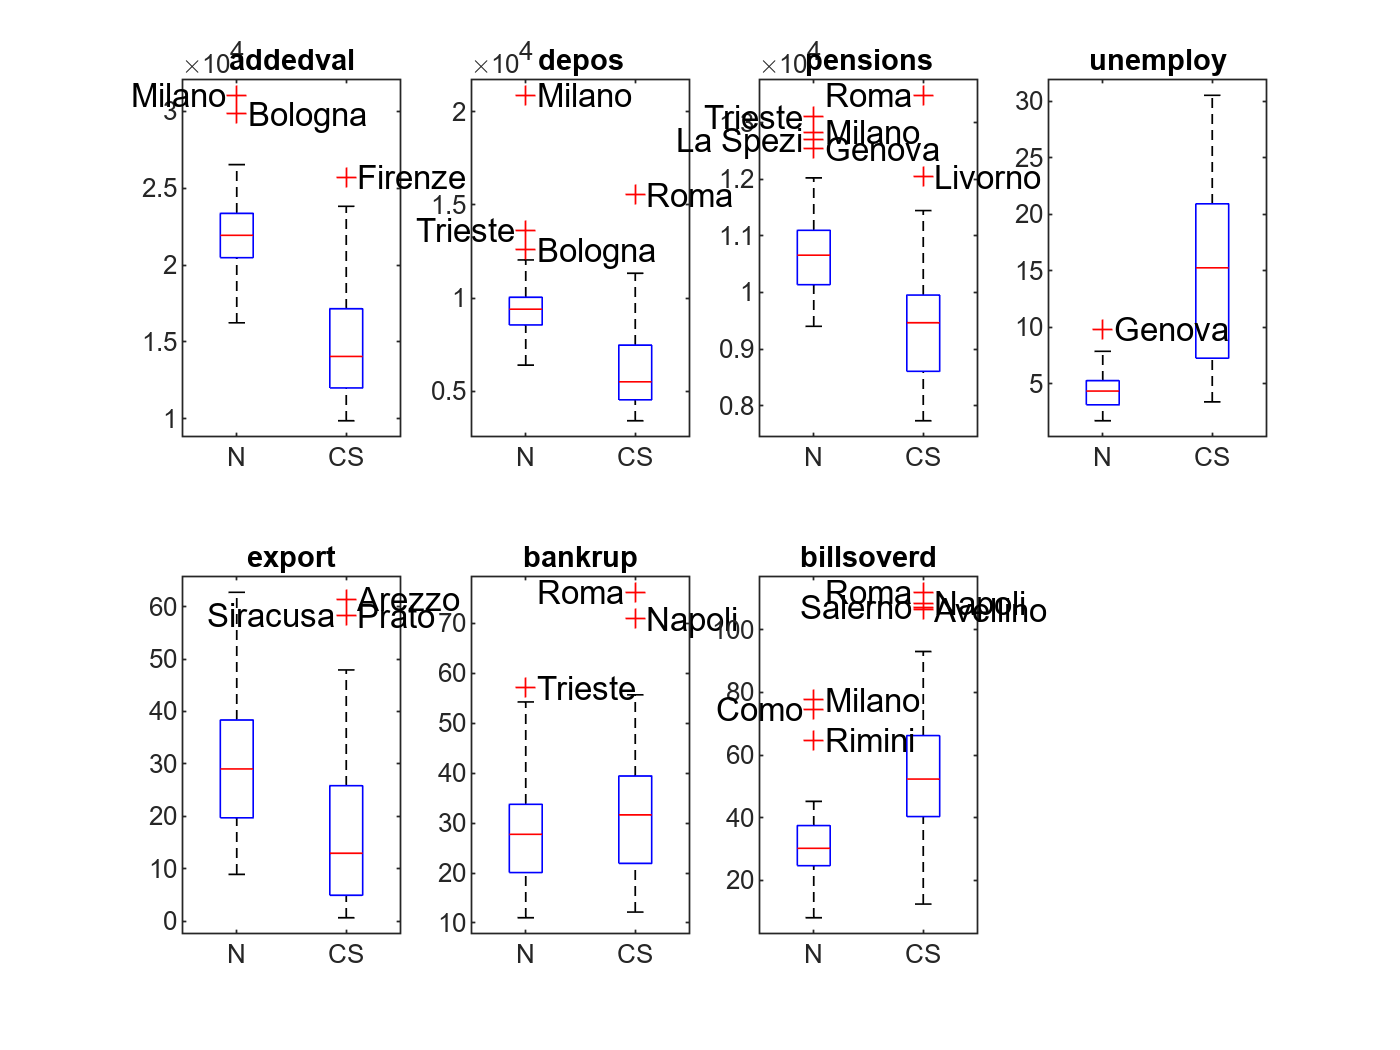

% Analisi tramite boxplot utilizzando la variabile di raggruppamento
% Il  pannello j contiene il boxplot della variabile j suddiviso per zona
% di appartenenza
for j=1:p
    subplot(2,4,j)
    boxplot(citiesItaly{:,j},groupvariable)
    add2boxplot(citiesItaly(:,j),groupvariable)
    title(vnames{j})
end

% Commento al grafico. Le distribuzioni suddivise per zona di appartenenza
% generalmente presentano asimmetria positiva. Le regioni del nord sono
% caratterizzate da valori più elevati per quanto riguarda le variabili
% valori aggiunto prodotto, depositi, pensioni ed export e valori inferiori
% per quantio riguarda il tasso di disoccupazione e l'indicatore legato ai
% protesti (billsoverdue). La distribuzione dell'indicatore di bancarotta è
% simile per le province del nord e centro sud. Roma e Napoli sono
% caratterizzate da valori eccessivamente elevati per l'indicotore di
% bancarotta. Per quanto riguarda l'indicatore dei protesti le 3 unità
% anomale per il centro nord (Como, Milano e Rimini) presentano valori che
% si collocano vicino al terzo quartile per le province del centro sud. Le
% province di Roma, Napoli, Salerno e Avellino nell'ambito delle province
% del centro sud presentano valori eccezionalemente grandi di questo
% indicatore.



## 2) Densità di frequenza

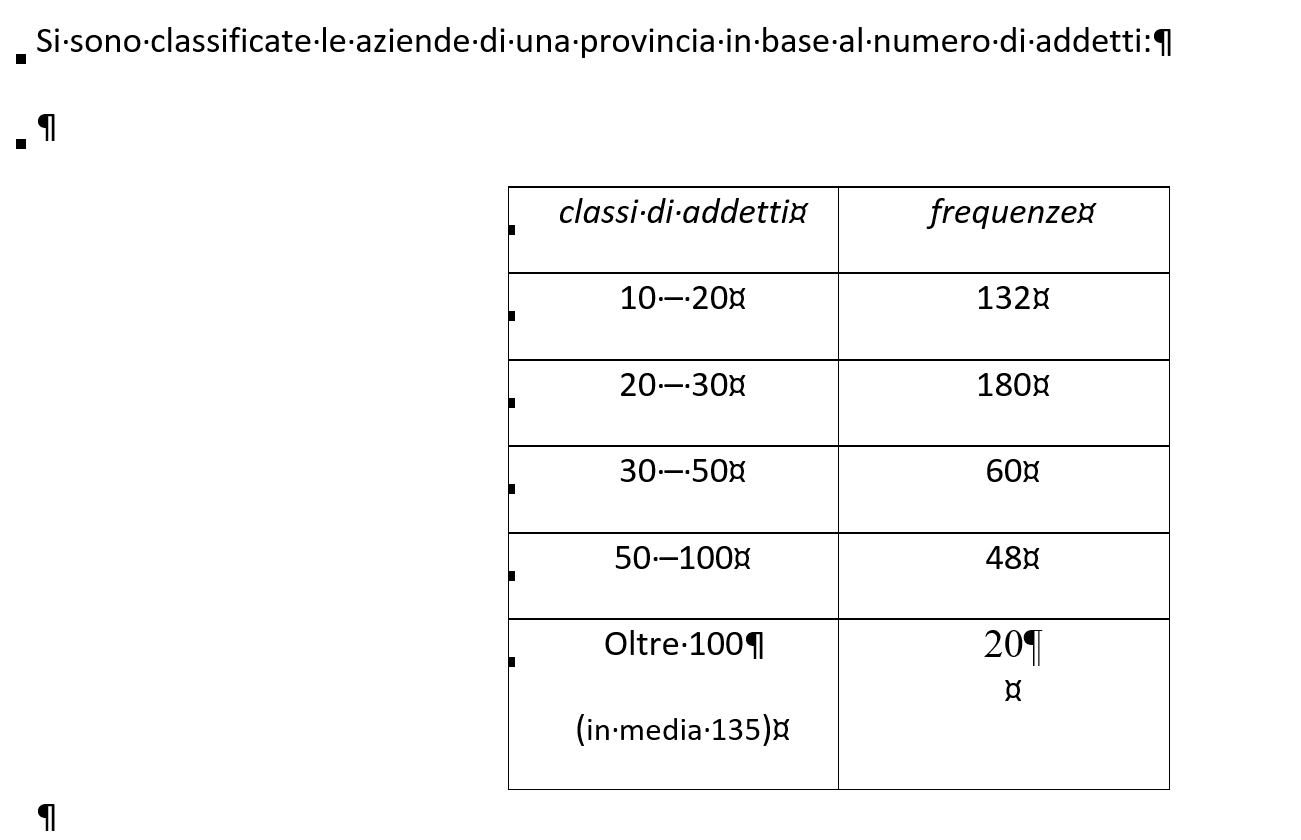

Si rappresenti graficamente, mediante istogrammi, la distribuzione del numero di addetti e si commentino le informazioni traibili da tale rappresentazione.

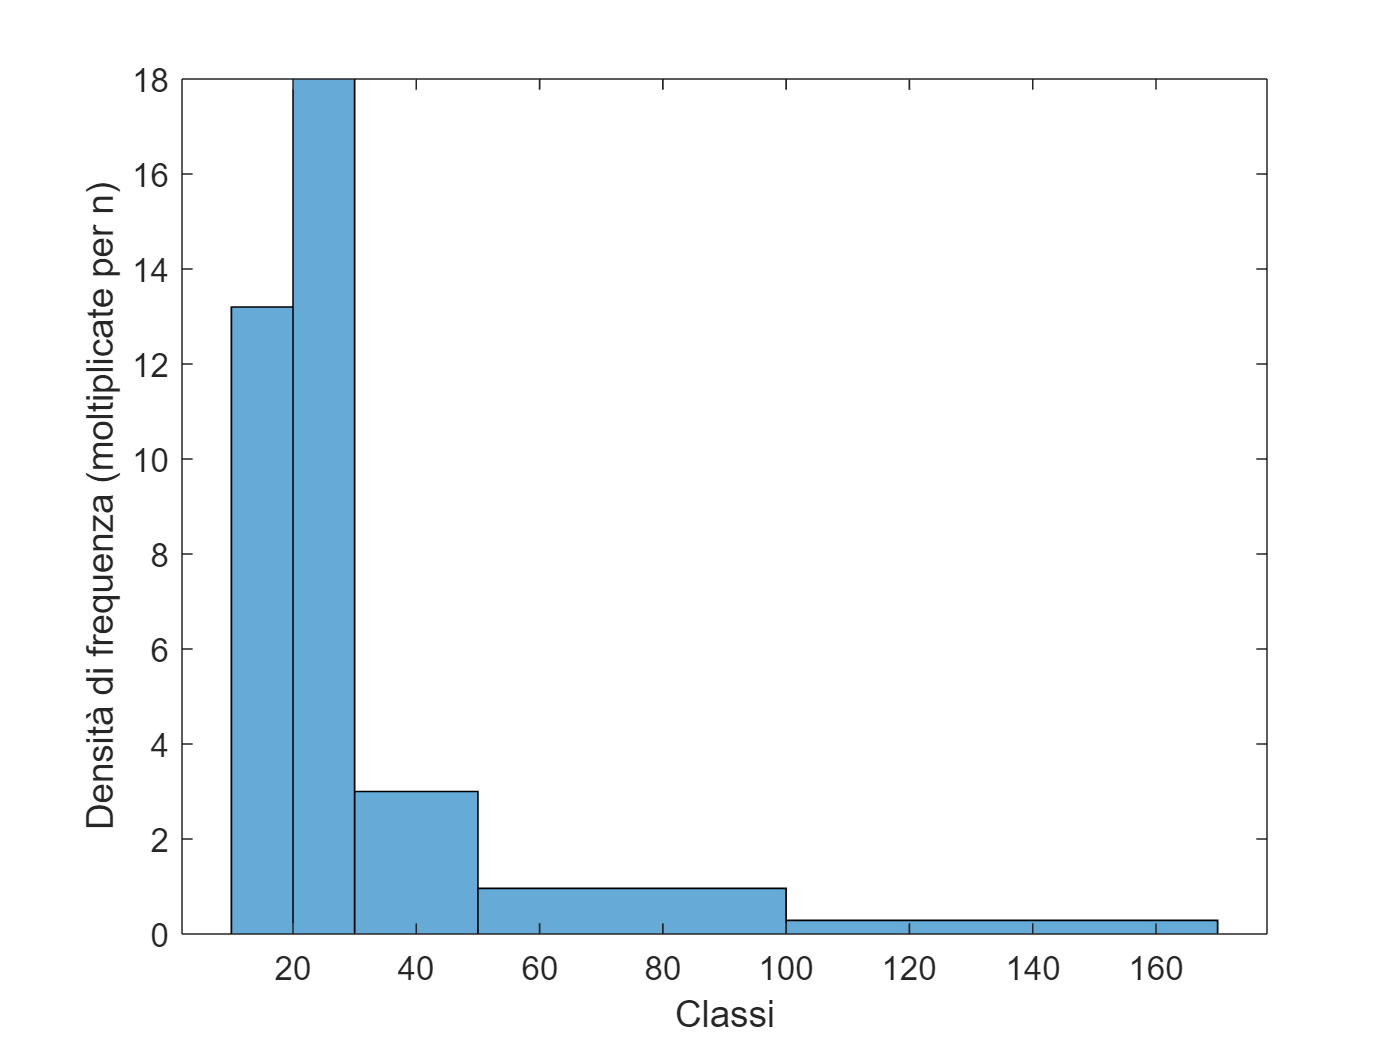

figure
% Nella raappresentazione grafica si devono utilizzare le densità di frequenza (moltiplicate per n).
% Le densità di frequenza sono definite come le frequenze relative divise
% per l'ampiezza della classe.
ni=[132; 180; 60; 48; 20];

% amp = vettore che contiene l'ampiezza delle classi
amp=[10; 10; 20; 50; 70];
% dens = densità di frequenza (moltiplicate per n)
dens=ni./amp;
classi=cumsum([10;amp]);
histogram('BinEdges',classi','BinCounts',dens)
xlabel('Classi')
ylabel('Densità di frequenza (moltiplicate per n)')

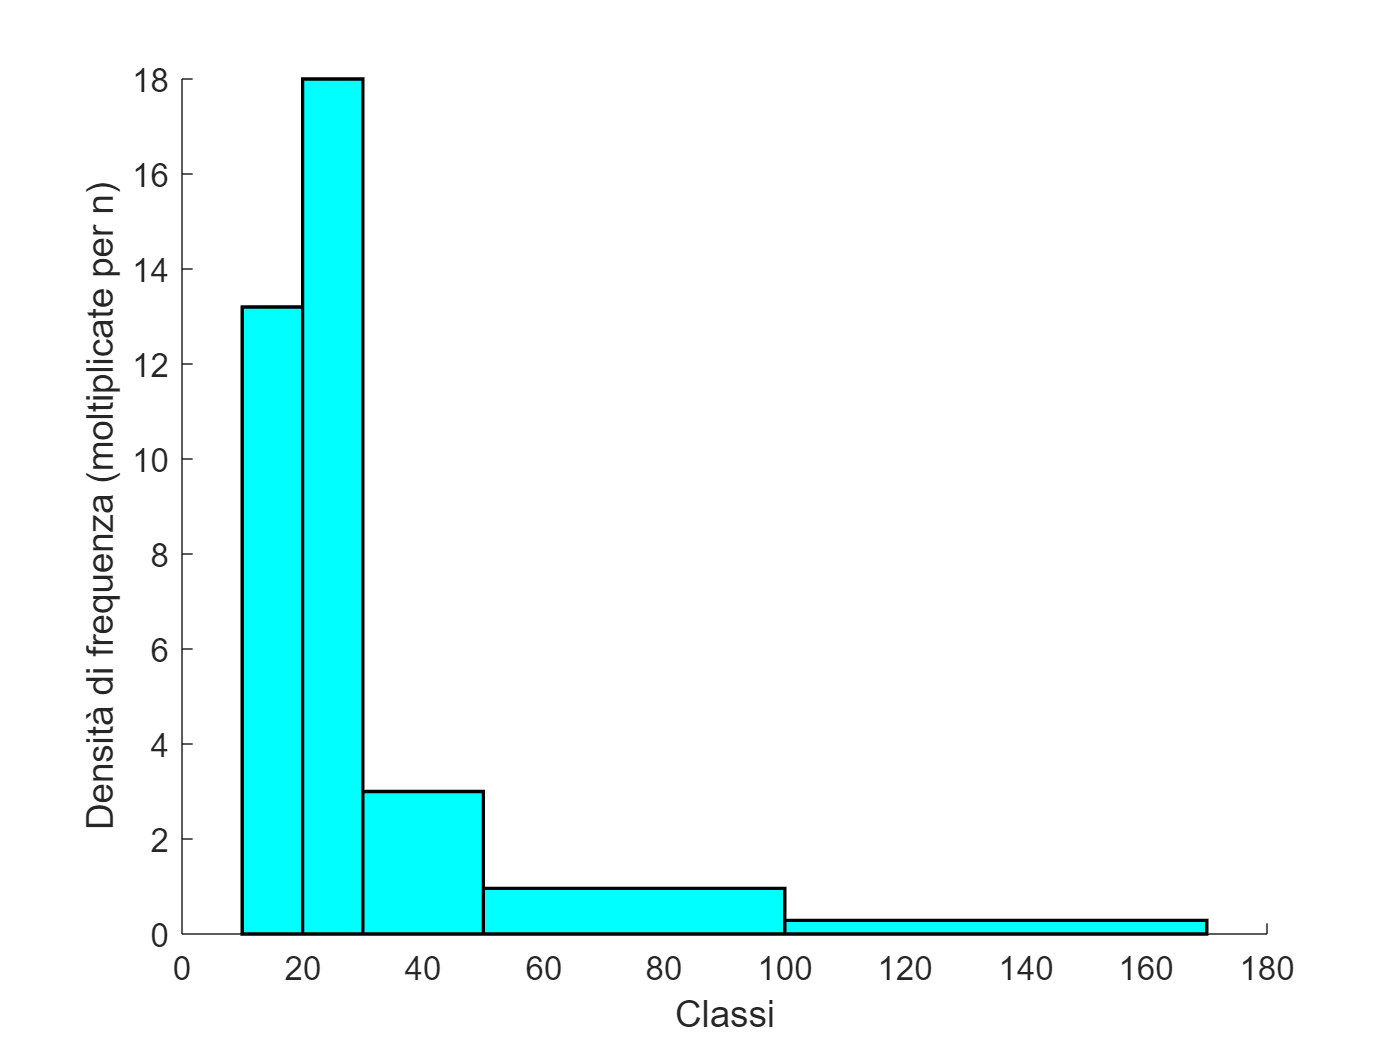

% L'istruzione figure di seguito è necessario altrimenti il nuovo grafico
% sovrascrive il precedente
figure
% Alternativamente era possibile usare anche la funzione barVariableWidth
% di FSDA toolbox
barVariableWidth(dens,classi)
xlabel('Classi')
ylabel('Densità di frequenza (moltiplicate per n)')

## 3) TABELLE PIVOT

La table bank_data (che si carica in memoria tramite l'istruzione load bank_data.mat) contiene la quantità di prodotti posseduti da un insieme di clienti di una banca.

I prodotti sono i seguenti

- X1 = Personal loans,

- X2 = Financing and hire-purchase,

- X3 = Mortgages,

- X4 = Life insurance

- X5 = Share account

- X6 = Bond account

- X7 = Current account

- X8 = Salary deposits

- X9 = Debit cards

- X10 = Credit cards

- X11 =Telephone banking

- X12 = Domestic direct debits

- X13 = Money transfers.

- y = Profit/loss

La variabile etichettata come y=Profit/loss contiene i profitti (perdite) realizzati dalla banca su ogni consumatore.

Costruire la tabella di contingenza tra le variabili Numero di carte di credito posseduto (sulle righe) e Numero di carte di debito possedute (sulle colonne). Raggruppare in un'unica classe >=4 le modalità >4.

Costruire una tabella pivot che riporta sulle righe e colonne le stesse variabili ma all'interno di ogni cella il profitto medio realizzato dalla banca. Anteprima output

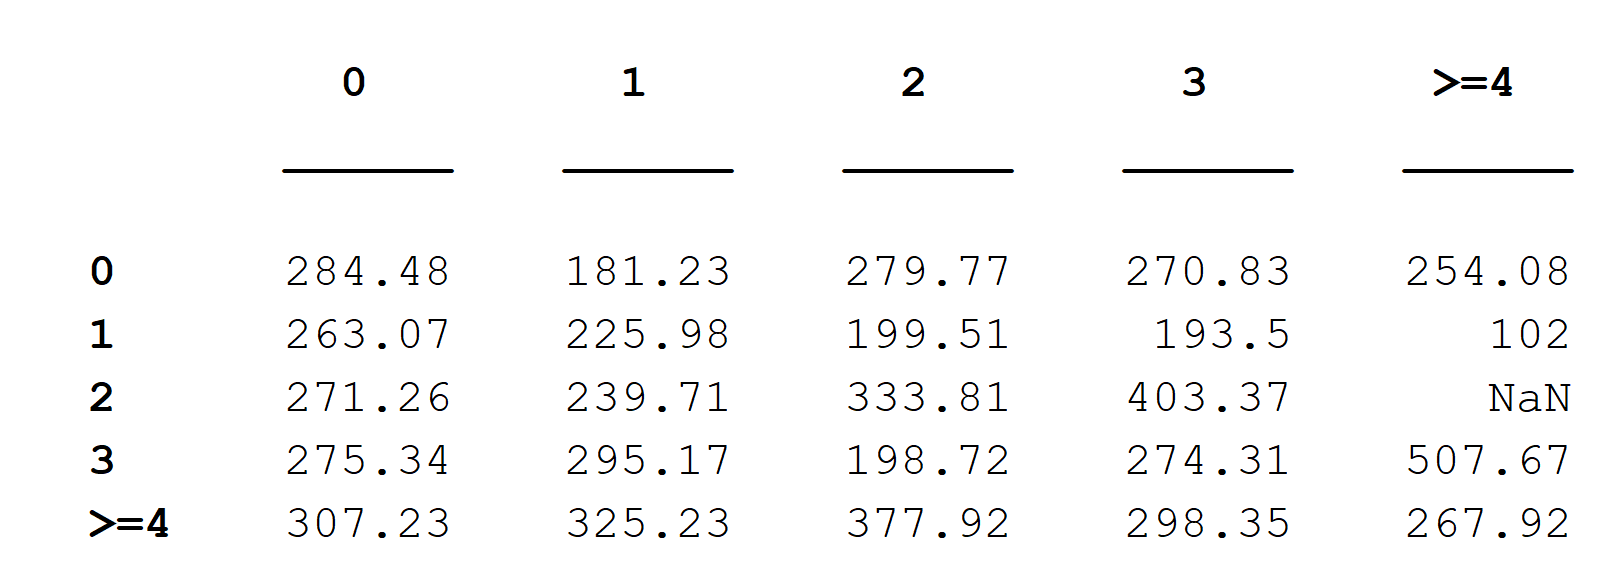

load bank_data.mat
carteCredito=bank_data.x10;
carteDebito=bank_data.x9;
soglia=4;
carteCredito(carteCredito>soglia)=soglia;
carteDebito(carteDebito>soglia)=soglia;
[N,~,~,eti]=crosstab(carteCredito,carteDebito);
eti(end,:)={'>=4' '>=4'};
Ntable=array2table(N,"RowNames",eti(:,1),"VariableNames",eti(:,2));
disp("Tabella di contingenza tra il numero di carte di credito")

Tabella di contingenza tra il numero di carte di credito


disp("ed il numero di carte di debito possedute")

ed il numero di carte di debito possedute


disp(Ntable)

            0      1     2     3    >=4
           ___    ___    __    _    ___

    0      580    382    39    1     1 
    1      105     90    21    2     1 
    2      245    203    30    6     0 
    3       80     85    15    4     1 
    >=4     20     26     6    5     1 



% Tab=table con le 3 variabili che mi intessano per costruire la tabella
% pivot
profitti=bank_data.y;
Tab=table(carteCredito, carteDebito, profitti);
funz=@mean;
% funz=@numel;
% unstack (Table iniziali, variabili all'interno, variabile sulle colonne
tabpivot=unstack(Tab,"profitti","carteDebito",...
    'AggregationFunction',funz,"GroupingVariables","carteCredito", ...
    'VariableNamingRule','preserve');
tabpivot=sortrows(tabpivot,"carteCredito");
tabpivot.Properties.RowNames=eti(:,1);
tabpivot=tabpivot(:,2:end);
tabpivot.Properties.VariableNames=eti(:,1);
disp(tabpivot)

             0         1         2         3        >=4  
           ______    ______    ______    ______    ______

    0      284.48    181.23    279.77    270.83    254.08
    1      263.07    225.98    199.51     193.5       102
    2      271.26    239.71    333.81    403.37       NaN
    3      275.34    295.17    198.72    274.31    507.67
    >=4    307.23    325.23    377.92    298.35    267.92



% tabella pivot tra il numero di carte di credito possedute ed il numero di
% carte di debito. I numeri all'interno della table indicano il profitto
% medio realizzato dalla banca.


## 4) Distribuzione di frequenze di fenomeni qualitativi ordinali

Il vettore di seguito contiene la codifica numerica dei giudizi ottenuti da 15 studenti in un determinato esame.

3	2	3	5	1	1	4	5	1	3	5	2	1	1	2

I numeri 1:5 corrispondono alle seguenti modalità

1=insufficiente

2=sufficiente

3=discreto

4=buono

5=ottimo

Costruire un vettore di tipo categorical denominato votic con i giudizi originali (ad esempio il numero 3 deve essere sostituito con discreto) mantenendo l'ordinamento tra le modalità:

insufficiente < sufficiente<discreto< buono< ottimo.

Creare  la distribuzione di frequenze mostrando le frequenze assolute e percentuali di ogni modalità (v. anteprima output di seguito)

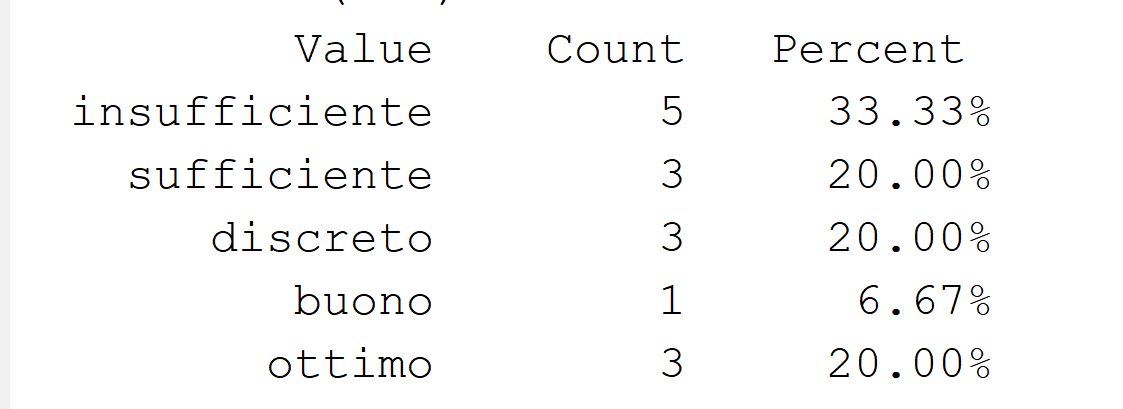

Mostrare graficamente la distribuzione delle  frequenze tramite barre orizzontali, rimuovendo il riempimento di colore delle barre.

Calcolare la modalità mediana. Calcolare la mediana del vettore votic fra coloro che hanno passato l'esame (in altri termini calcolare la mediana dei voti dopo aver escluso le votazioni insufficienti).

num=[3	2	3	5	1	1	4	5	1	3	5	2	1	1	2];
Modalita=["insufficiente" "sufficiente" "discreto" "buono" "ottimo"]';
% Viene creato il vettore cateogrico ordinale.
% I numeri 1:5 sono codificati con le modalità presenti nel vettore
% denominato Modalita
votic=categorical(num,(1:5),Modalita,'Ordinal',true);
disp('Distribuzione di frequenza dei voti')

Distribuzione di frequenza dei voti


tabulate(votic)

          Value    Count   Percent
  insufficiente        5     33.33%
    sufficiente        3     20.00%
       discreto        3     20.00%
          buono        1      6.67%
         ottimo        3     20.00%


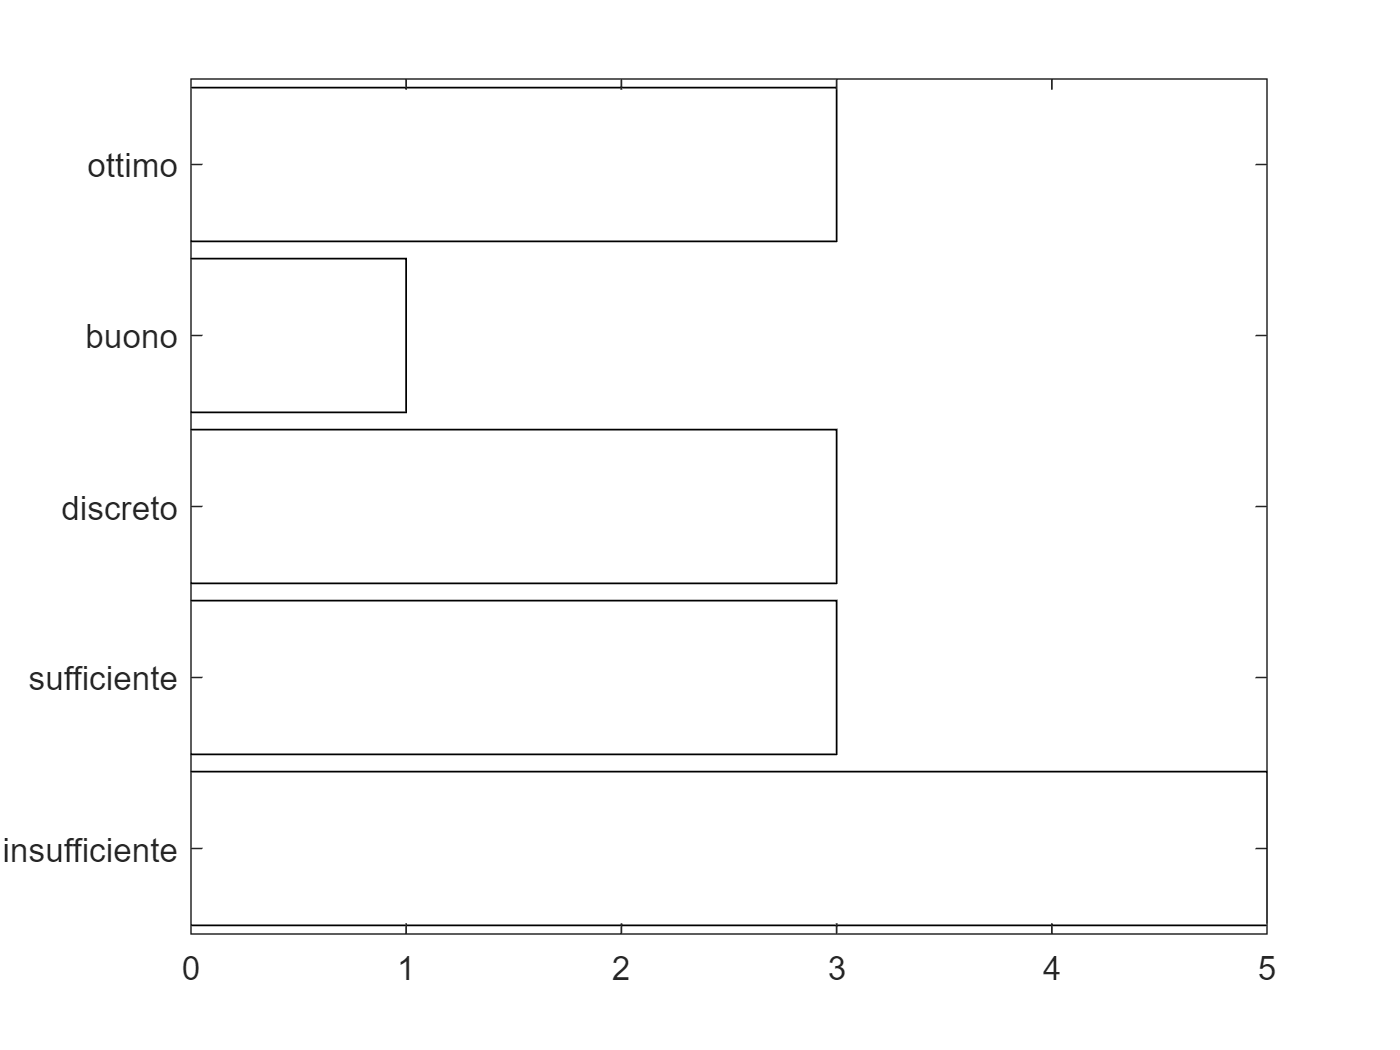


h=histogram(votic,'FaceColor','none','Orientation','horizontal');

% osservazione h.Values contiene le frequenze
disp('Mediana dei voti')

Mediana dei voti


median(votic)

ans = categorical
     sufficiente 


disp('Mediana dei voti tra coloro che hanno passato l''esame')

Mediana dei voti tra coloro che hanno passato l'esame


median(votic(votic>"insufficiente"))

ans = categorical
     discreto 
